# ME-422 Multivariable control: exercise session on CSTR - solutions

In this exercise, we consider the continuous-time nonlinear dynamics of the CSTR described by the following state-space equations:

$\dot{c} \left(t\right)=\frac{q}{V}\left(c_f \left(t\right)-c\left(t\right)\right)-k_0 \;e^{-\frac{E}{R\;T\left(t\right)}} c\left(t\right)$,

$\dot{T} \left(t\right)=\frac{U\;A}{V\;\rho {\;c}_p \;}\left(T_c \left(t\right)-T\left(t\right)\right)+\frac{q}{V}\left(T_f -T\left(t\right)\right)-\frac{\Delta H}{\rho \;c_p }k_0 \;e^{-\frac{E}{R\;T\left(t\right)}} c\left(t\right)$.

We start by cleaning the workspace and loading the data of the CSTR

clc; close all; clear; 
% Load data
run data_CSTR.m

## Point 1: Simulink model

The Simulink model of the system can be found in the block CSTR of the `CSTR_ol.slx` file. The ‘Interpreted MATLAB function’ is implemented in the `cstrfun.m` file.

## Point 2: Equilibrium

We calculate the necessary inputs $\left({\bar{c} }_f ,{\bar{T} }_c \right)$ that give the equilibrium at $\bar{c} =0\ldotp 5\;\frac{\textrm{mol}}{\mathrm{L}}$ and $\bar{T} =350\;\mathrm{K}$.

Define the equilibrium:

cbar = 0.5;
Tbar = 350;

Then, the corresponding inputs are such that $\dot{c} \left(t\right)=0$ and $\dot{T} \left(t\right)=0$:

cfbar = (q/V * cbar + ko * cbar * exp(-ER/Tbar))/(q/V);
Tcbar = (DH/(rho*cp)*ko*cbar*exp(-ER/Tbar) - ...
    q/V*(Tf - Tbar))*(V*rho*cp/UA) + Tbar;
fprintf("Inputs: cfbar = %.1f mol/L and Tcbar = %.0f K.\n",cfbar,Tcbar)

Inputs: cfbar = 1.0 mol/L and Tcbar = 300 K.


We validate the calculations by simulating the system provided in `CSTR_ol.slx` with initial conditions at $\left(\bar{c} ,\bar{T} \right)$ and inputs $\left({\bar{c} }_f ,{\bar{T} }_c \right)$.

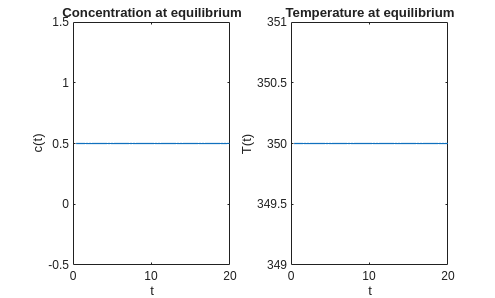

% Set initial conditions
cbar_sim = cbar; Tbar_sim = Tbar; 
cfbar_sim = cfbar; Tcbar_sim = Tcbar;
% Simulate the system
ol_eq = sim("CSTR_ol.slx");
% Plot results
figure
subplot(121)
plot(ol_eq.c, 'LineWidth', 1)
title("Concentration at equilibrium"); xlabel('t'); ylabel("c(t)") 
subplot(122)
plot(ol_eq.T, 'LineWidth', 1)
title("Temperature at equilibrium"); xlabel('t'); ylabel("T(t)")

disp("As expected, the system initialized at the equilibrium stays there.")

As expected, the system initialized at the equilibrium stays there.


As expected, the system stays in the calculated equilibrium $\left(\bar{c} ,\bar{T} \right)$ when we consider $\left({\bar{c} }_f ,{\bar{T} }_c \right)$as inputs.

## Point 3: Perturbations around equilibrium

We simulate (four times) the model when a ±1% disturbance on the initial conditions around the equilibrium is added.

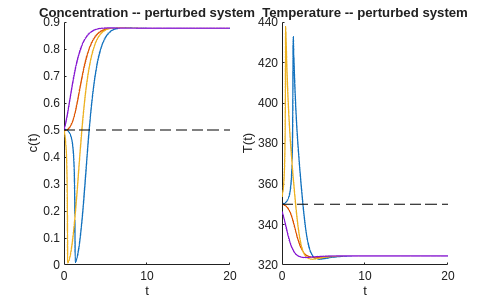

% Set initial conditions and simulate the system
cbar_sim = cbar*1.01; Tbar_sim = Tbar;
ol_p1 = sim("CSTR_ol.slx");
cbar_sim = cbar*0.99; Tbar_sim = Tbar;
ol_p2 = sim("CSTR_ol.slx");
cbar_sim = cbar; Tbar_sim = Tbar*1.01;
ol_p3 = sim("CSTR_ol.slx");
cbar_sim = cbar; Tbar_sim = Tbar*0.99;
ol_p4 = sim("CSTR_ol.slx");
% Plot resutls
figure
subplot(121); hold on;
plot(ol_p1.c,'LineWidth', 1)
plot(ol_p2.c,'LineWidth', 1)
plot(ol_p3.c,'LineWidth', 1)
plot(ol_p4.c,'LineWidth', 1)
plot([ol_p1.tout(1), ol_p1.tout(end)], [cbar,cbar], 'k--')
title("Concentration -- perturbed system"); xlabel('t'); ylabel("c(t)") 
subplot(122); hold on;
plot(ol_p1.T,'LineWidth', 1)
plot(ol_p2.T,'LineWidth', 1)
plot(ol_p3.T,'LineWidth', 1)
plot(ol_p4.T,'LineWidth', 1)
plot([ol_p1.tout(1), ol_p1.tout(end)], [Tbar,Tbar], 'k--')
title("Temperature -- perturbed system"); xlabel('t'); ylabel("T(t)")

fprintf("Adding a perturbation of 1%% to the initial conditions\n" + ...
    "(cbar,Tbar), does not allow the system to recover towards\n" + ...
    "the calculated equilibrium.")

Adding a perturbation of 1% to the initial conditions
(cbar,Tbar), does not allow the system to recover towards
the calculated equilibrium.

Note that no conclusion can be drawn about the stability of this equilibrium of the nonlinear system. In fact, we cannot say whether the equilibrium is unstable or stable, as we may have simply chosen an initial condition that lie outside of the region of attraction (ROA) of the equilibrium.

## Point 4: Linearization of the continuous-time system around $\left(\bar{c} ,\bar{T} \right)$ with inputs $\left({\bar{c} }_f ,{\bar{T} }_c \right)$:

For obtaining the linearization matrices using Simulink, we connect the `In1`, `In2`, `Out1` and `Out2` blocks at the inputs and outputs of the model in the `CSTR_ol.slx` file. Moreover, we add a Timed_Based_Linearization block, and we set the 'Linearization time' equal to the total simulation time.

The following code allows us to obtain the matrices that characterize the linearized system dynamics around $\left(\bar{c} ,\bar{T} \right)$ with inputs $\left({\bar{c} }_f ,{\bar{T} }_c \right)$.

% Set initial conditions
cbar_sim = cbar; Tbar_sim = Tbar; 
cfbar_sim = cfbar; Tcbar_sim = Tcbar;
% Simulate the system
sim('CSTR_ol');
% Obtain the A,B,C,D matrices that characterize the linearized system:
A = CSTR_ol_Timed_Based_Linearization.a;
B = CSTR_ol_Timed_Based_Linearization.b;
C = CSTR_ol_Timed_Based_Linearization.c;
D = CSTR_ol_Timed_Based_Linearization.d;

We calculate the eigenvalues of the $A$ matrix that characterizes the evolution of the linearized system.

eigs = eig(A)

eigs =    -0.4543
    2.8334


disp("The CT linearized model around (cbar, Tbar) is unstable.")

The CT linearized model around (cbar, Tbar) is unstable.


The continuous-time linearized model around $\left(\bar{c} ,\bar{T} \right)$ with inputs $\left({\bar{c} }_f ,{\bar{T} }_c \right)$ is unstable since it has an eigenvalue at 2.83. Since the linearized system has a pole with positive real part, then the nonlinear system is unstable at that equilibrium.

## Point 5a: Equilibrium around another operation point 

We load the data of the file `CSTR_eq2.m`, which gives us a new equilibrium point of the system $\left(\tilde{c} ,\tilde{T} \right)$.

run CSTR_eq2.m

We verify that $\left(\tilde{c} ,\tilde{T} \right)$ is indeed an equilibrium point when considerting $\left({\bar{c} }_f ,{\bar{T} }_c \right)$ as inputs.

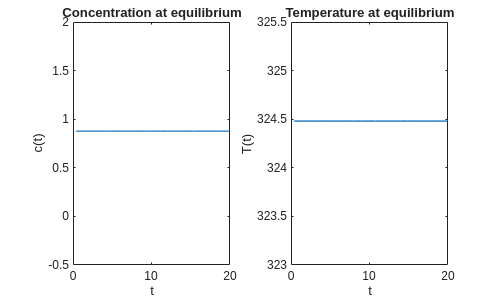

% Set the initial conditions
cbar_sim = ctilde; Tbar_sim = Ttilde; 
% Set the inputs
cfbar_sim = cfbar; Tcbar_sim = Tcbar;
% Simulate the system
ol_eq = sim("CSTR_ol.slx");
% Plot results
figure
subplot(121)
plot(ol_eq.c, 'LineWidth', 1)
title("Concentration at equilibrium"); xlabel('t'); ylabel("c(t)") 
subplot(122)
plot(ol_eq.T, 'LineWidth', 1)
title("Temperature at equilibrium"); xlabel('t'); ylabel("T(t)")


fprintf("(ctilde, Ttilde) is an equilibrium of the system when\n" + ...
    "applying (cfbar, Tcbar) as inputs.")

(ctilde, Ttilde) is an equilibrium of the system when
applying (cfbar, Tcbar) as inputs.

## Point 5b: Linearization around $\left(\tilde{c} ,\tilde{T} \right)$

We get the linearized matrices by exploiting the Timed_Based_Linearization block.

% Set the initial conditions
cbar_sim = ctilde; Tbar_sim = Ttilde; 
cfbar_sim = cfbar; Tcbar_sim = Tcbar;
% Simulate the system
sim('CSTR_ol');
% Get the linearized matrices
A2 = CSTR_ol_Timed_Based_Linearization.a;
B2 = CSTR_ol_Timed_Based_Linearization.b;
C2 = CSTR_ol_Timed_Based_Linearization.c;
D2 = CSTR_ol_Timed_Based_Linearization.d;

We calculate the eigenvalues of the $A_2$ matrix that characterizes the evolution of the linearized system.

eigs = eig(A2)

eigs =   -1.0486 + 0.5390i
  -1.0486 - 0.5390i


disp("The CT linearized model around (cbar, Tbar) is stable.")

The CT linearized model around (cbar, Tbar) is stable.


The continuous-time linearized model around $\left(\tilde{c} ,\tilde{T} \right)$ is globally asymptotically stable since all its eigenvalues have negative real part. Then, the nonlinear system is locally stable around $\left(\tilde{c} ,\tilde{T} \right)$ with inputs $\left({\bar{c} }_f ,{\bar{T} }_c \right)$.

#### Validation

We simulate (four times) the nonlinear model when a ±1% disturbance on the initial conditions around the equilibrium is added.

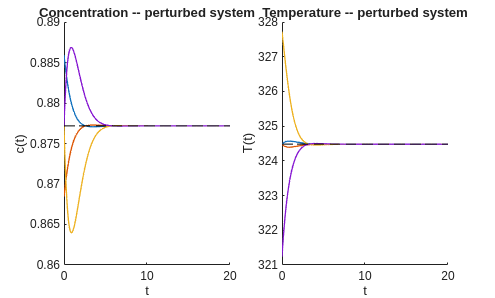

% Set initial conditions and simulate the system
cbar_sim = ctilde*1.01; Tbar_sim = Ttilde;
ol_p5 = sim("CSTR_ol.slx");
cbar_sim = ctilde*0.99; Tbar_sim = Ttilde;
ol_p6 = sim("CSTR_ol.slx");
cbar_sim = ctilde; Tbar_sim = Ttilde*1.01;
ol_p7 = sim("CSTR_ol.slx");
cbar_sim = ctilde; Tbar_sim = Ttilde*0.99;
ol_p8 = sim("CSTR_ol.slx");
% Plot results
figure
subplot(121); hold on
plot(ol_p5.c, 'LineWidth', 1)
plot(ol_p6.c, 'LineWidth', 1)
plot(ol_p7.c, 'LineWidth', 1)
plot(ol_p8.c, 'LineWidth', 1)
plot([ol_p5.tout(1), ol_p5.tout(end)], [ctilde,ctilde], 'k--')
title("Concentration -- perturbed system"); xlabel('t'); ylabel("c(t)") 
subplot(122); hold on
plot(ol_p5.T, 'LineWidth', 1)
plot(ol_p6.T, 'LineWidth', 1)
plot(ol_p7.T, 'LineWidth', 1)
plot(ol_p8.T, 'LineWidth', 1)
plot([ol_p5.tout(1), ol_p5.tout(end)], [Ttilde,Ttilde], 'k--')
title("Temperature -- perturbed system"); xlabel('t'); ylabel("T(t)")

fprintf("When adding a perturbation of 1%% to the initial conditions\n" + ...
    "(ctilde,Ttilde), the system returns to the same equilibrium.")

When adding a perturbation of 1% to the initial conditions
(ctilde,Ttilde), the system returns to the same equilibrium.

Since the perturbed initial conditions are inside the region of attraction (ROA), the nonlinear system converges to the equilibruim $\left(\tilde{c} ,\tilde{T} \right)$, showing that this is a (possibly locally) stable equilibrium for the nonlinear system.